clearvars
load('combinedTable.mat', 'combinedTable');

folderPath = fullfile(pwd, 'models');  % pwd = current directory

% Create folder if it doesn't exist
if ~exist(folderPath, 'dir')
    mkdir(folderPath);
end

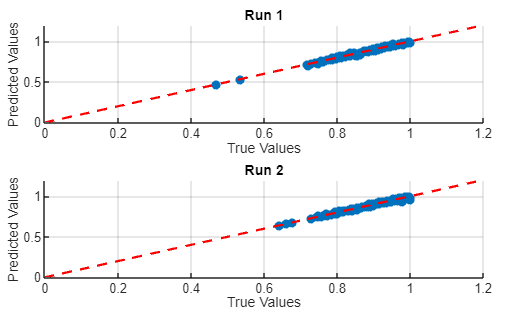

featNames = {'Cch_rate','Cdch_rate','T_K','SOC_store','t_h','FEC','DOD_pct','Category','mean_SOC'};   % raw features
targetCol = 'SOH';  
numRuns = 2;  

rmseTrainAll = zeros(numRuns,1);
maeTrainAll  = zeros(numRuns,1);
r2TrainAll   = zeros(numRuns,1);

rmseValAll   = zeros(numRuns,1);
maeValAll    = zeros(numRuns,1);
r2ValAll     = zeros(numRuns,1);

rmseTestAll  = zeros(numRuns,1);
maeTestAll   = zeros(numRuns,1);
r2TestAll    = zeros(numRuns,1);

r2   = @(yPred,yTrue) 1 - sum((yPred(:) - yTrue(:)).^2)/sum((yTrue(:) - mean(yTrue(:))).^2);

tic;
numRows = ceil(sqrt(numRuns));
numCols = ceil(numRuns/numRows); 

figureHandle = figure('Position', [100, 100, numRows*1618, numRows*1000]);  
t = tiledlayout(numRows, numCols, 'Padding','compact','TileSpacing','compact');


for Run = 1:numRuns
    % Set a seed for reproducibility
    rng(Run*5) % choose any integer seed
    % Get number of rows
    numRows = height(combinedTable);
    % Create a random permutation of row indices
    shuffledIndices = randperm(numRows);
    % Apply the permutation to shuffle the table
    shuffledTable = combinedTable(shuffledIndices, :);
    
    X = shuffledTable(:, featNames);
    Y = shuffledTable.(targetCol);
    
    for f = 1:length(featNames)
    colData = X.(featNames{f});
        if iscellstr(colData) || isstring(colData) || iscategorical(colData)
            X.(featNames{f}) = double(categorical(colData));
        end
    end

    % Convert table to numeric array (categorical → dummy vars)
    X_mat = table2array(X);  % all columns are now numeric

    Y_vec = double(Y);   % Ensure numeric target
       
    X_mat(isnan(X_mat)) = 0;

    n = height(shuffledTable);

    trainRatio = 0.7; 
    valRatio   = 0.15; 
    testRatio  = 0.15;
    
    idxTrain = 1:floor(trainRatio*n);
    idxVal   = (idxTrain(end)+1):(idxTrain(end)+floor(valRatio*n));
    idxTest  = (idxVal(end)+1):n;
    
    X_train = X_mat(idxTrain,:);
    Y_train = Y_vec(idxTrain);
    
    X_val   = X_mat(idxVal,:);
    Y_val   = Y_vec(idxVal);
    
    X_test  = X_mat(idxTest,:);
    Y_test  = Y_vec(idxTest);

    mu = mean(X_train);
    sigma = std(X_train);
    
    X_train = (X_train - mu) ./ sigma;
    X_val   = (X_val - mu) ./ sigma;
    X_test  = (X_test - mu) ./ sigma;

   
layers = [
    featureInputLayer(9,'Name','in')  % 9 features

    fullyConnectedLayer(64,'Name','fc1')
    reluLayer('Name','relu1')

    fullyConnectedLayer(32,'Name','fc2')
    reluLayer('Name','relu2')

    fullyConnectedLayer(1,'Name','out')
    sigmoidLayer('Name','sigOut')
    regressionLayer('Name','reg')
];

miniB = 32;
opts = trainingOptions('adam', ...
    'InitialLearnRate',0.001498, ...
    'MaxEpochs',100, ...
    'MiniBatchSize',miniB, ...
    'Shuffle','every-epoch', ...
    'ValidationData',{X_val,Y_val}, ...
    'ValidationFrequency',max(1,floor(size(X_train,1)/miniB)), ...
    'ValidationPatience',72, ...
    'L2Regularization',0.000001, ...
    'Verbose',false, ...
    'GradientThresholdMethod','l2norm' ...
    ,'GradientThreshold',1, ...
    'LearnRateSchedule','piecewise' , ...
    'LearnRateDropPeriod',100, ...
    'LearnRateDropFactor',0.84);
    % Train
    net = trainNetwork(X_train, Y_train, layers, opts);
    
  % Get predictions (no transposes needed)
    Y_train_pred = predict(net, X_train);
    Y_val_pred   = predict(net, X_val);
    Y_test_pred  = predict(net, X_test);
    
    % Ensure column vectors
    Y_train_pred = Y_train_pred(:);
    Y_val_pred   = Y_val_pred(:);
    Y_test_pred  = Y_test_pred(:);
    
    % --- Training metrics ---
    rmseTrainAll(Run) = sqrt(mean((Y_train - Y_train_pred).^2));
    maeTrainAll(Run)  = mean(abs(Y_train - Y_train_pred));
    r2TrainAll(Run)   = r2(Y_train_pred,Y_train);

    % --- Validation metrics ---
    rmseValAll(Run) = sqrt(mean((Y_val - Y_val_pred).^2));
    maeValAll(Run)  = mean(abs(Y_val - Y_val_pred));
    r2ValAll(Run)   = r2(Y_val_pred,Y_val);
    % --- Test metrics ---
    rmseTestAll(Run) = sqrt(mean((Y_test - Y_test_pred).^2));
    maeTestAll(Run)  = mean(abs(Y_test - Y_test_pred));
    r2TestAll(Run)   = r2(Y_test_pred,Y_test);
    modelname = sprintf('Run_%d_Seed_%d_RMSE_%.4f_MAE_%.4f_R2_%.4f.mat',...
        Run,Run*5,rmseTestAll(Run),maeTestAll(Run),r2TestAll(Run));
 
    save(fullfile('models', modelname) , 'net');

    nexttile
    scatter(Y_test, Y_test_pred, 'filled');
    hold on;
    plot([0, 1.2*max(Y_test)], [0, 1.2*max(Y_test)], 'r--', 'LineWidth', 1.5);
    hold off;
    xlabel('True Values');
    ylabel('Predicted Values');
    title(sprintf('Run %d', Run));
    grid on;
end 

figName = fullfile(folderPath, 'AllRuns_PredVsTrue.png');
exportgraphics(figureHandle, figName, 'Resolution', 300);



elapsedTime = toc;   % seconds
fprintf('Elapsed Time        : %.2f seconds\n', elapsedTime);

Elapsed Time        : 214.98 seconds



metricsTable = table((1:numRuns)', ...
rmseTrainAll, maeTrainAll, r2TrainAll, ...
rmseValAll, maeValAll, r2ValAll, ...
rmseTestAll, maeTestAll, r2TestAll, ...
'VariableNames', {'Run', ...
'RMSE_Train','MAE_Train','R2_Train', ...
'RMSE_Val','MAE_Val','R2_Val', ...
'RMSE_Test','MAE_Test','R2_Test'});

meanRow = {NaN, mean(rmseTrainAll), mean(maeTrainAll), mean(r2TrainAll), ...
               mean(rmseValAll), mean(maeValAll), mean(r2ValAll), ...
               mean(rmseTestAll), mean(maeTestAll), mean(r2TestAll)};

stdRow  = {NaN, std(rmseTrainAll), std(maeTrainAll), std(r2TrainAll), ...
               std(rmseValAll), std(maeValAll), std(r2ValAll), ...
               std(rmseTestAll), std(maeTestAll), std(r2TestAll)};

% Append mean and std as extra rows
metricsTable = [metricsTable; ...
    cell2table(meanRow, 'VariableNames', metricsTable.Properties.VariableNames); ...
    cell2table(stdRow,  'VariableNames', metricsTable.Properties.VariableNames)];

% Optional: label these rows
metricsTable.Run = string(metricsTable.Run);  % convert numeric to string
metricsTable.Run(end-1:end) = ["Mean"; "Std"];% Display the table
disp(metricsTable);

     Run      RMSE_Train    MAE_Train     R2_Train      RMSE_Val      MAE_Val       R2_Val      RMSE_Test      MAE_Test      R2_Test 
    ______    __________    __________    _________    __________    __________    _________    __________    __________    _________

    "1"        0.0077166      0.005389      0.99089     0.0098372     0.0065073       0.9804     0.0075317     0.0054073      0.99136
    "2"         0.008641     0.0058013      0.98788      0.009671       0.00661      0.98722     0.0089295     0.0061807      0.98687
    "Mean"     0.0081788     0.0055951      0.98938     0.0097541     0.0065586      0.98381     0.0082306      0.005794   


% Construct filename
csvName = fullfile(folderPath, 'Metrics_AllRuns.csv');

% Export table to CSV
writetable(metricsTable, csvName);

disp(['Metrics table saved as: ', csvName]);

Metrics table saved as: C:\Users\Ali Khedr\Thesis_modelingg\BESS\ML_BESS\aly\models\Metrics_AllRuns.csv


% ===== Robust SHAP for FFNN (older/newer releases) =====
predictFcn = @(Z) predict(net, Z);      % net expects NORMALIZED inputs (X_val)

% 1) Make sure we have some query points
Xexpl = X_val;  if isempty(Xexpl), Xexpl = X_test; end
nq = max(1, min(512, size(Xexpl,1)));
Xq = Xexpl(1:nq, :);

% 2) Build explainer and COMPUTE Shapley values (older MATLAB needs 'fit')
exp = shapley(predictFcn, Xexpl);   % background = validation (or test) set
try
    % Newer versions may fill exp.ShapleyValues automatically; older need fit()
    SV = exp.ShapleyValues;
    if isempty(SV)
        R = fit(exp, Xq);           % <-- required on many releases
        SV = R.ShapleyValues;       % N×D
    end
catch
    R = fit(exp, Xq);
    SV = R.ShapleyValues;
end

% 3) If still empty, bail to permutation importance
if isempty(SV)
    warning('SHAP returned empty values (check X_val size and MATLAB release). Falling back to permutation importance.');
    baseRMSE = sqrt(mean((Y_val - predictFcn(X_val)).^2));
    imp_perm = zeros(1,numel(featNames));
    for j = 1:numel(featNames)
        Xp = X_val; Xp(:,j) = Xp(randperm(size(Xp,1)), j);
        rmse_j = sqrt(mean((Y_val - predictFcn(Xp)).^2));
        imp_perm(j) = rmse_j - baseRMSE;
    end
    [~,ixp] = sort(imp_perm,'descend');
    impTable = table(string(featNames(ixp))', imp_perm(ixp)', ...
        'VariableNames', {'Feature','Importance'});
    disp(impTable);  % done
else
    % 4) Global importance from SHAP
    gimp = mean(abs(SV), 1);
    [~,ix] = sort(gimp, 'descend');
    impTable = table(string(featNames(ix))', gimp(ix)', ...
        'VariableNames', {'Feature','SHAP_GlobalImportance'});
    disp(impTable);
end


